# Лабораторная работа №2

Соболев А.М.

Веснин М.?.

Вариант: 25

## Моделирование адаптивной системы в условиях возмущения

Модель объекта управления имеет следующий вид:


$$\dot{x} =\theta x+u+\delta$$


где $\delta$ - ограниченное внешнее возмущение.

Проведем моделирование такой системы с алгоритмом адаптации из прошлой лабораторной работы.

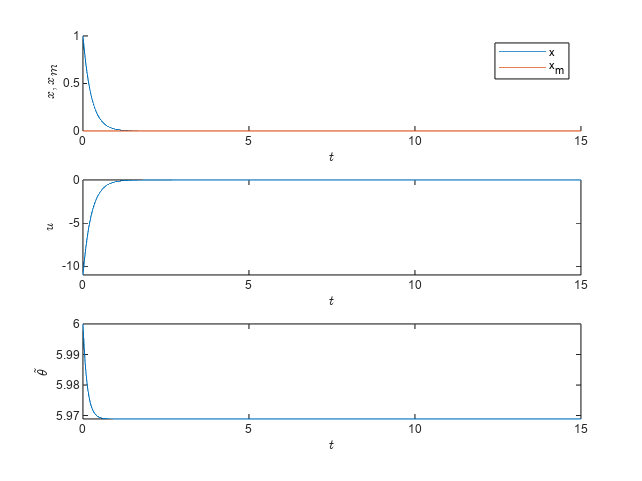

lambda = 10;
theta = 7;
t = 15; % Время симуляции

gamma = 0.25;
x_0 = 1;
theta_hat_0 = 1;


adapt = sim("Lab2_adaptive.slx");

% Графики
figure
subplot(3,1,1)
hold on
plot(adapt.simout.time, adapt.simout.signals.values(:,2)); % x
plot(adapt.simout.time, adapt.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(3,1,2)
plot(adapt.simout.time, adapt.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
subplot(3,1,3)
plot(adapt.simout.time, adapt.simout.signals.values(:,4)); % theta-theta_hat
ylabel('$$\tilde{\theta}$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

Как можно увидеть ошибка оценки параметра ($\tilde{\theta}$) остается постоянной поскольку алгоритм адаптации не может изменять оценку параметра при нулевой ошибке.

## Статическая обратная связь

Попробуем заменить алгоритм адаптации на статическую обратную связь


$$\hat{\theta} =-\gamma x\varepsilon$$


Регулируя параметр $\gamma$ можем влиять на систему.

### 
$$\gamma =1$$


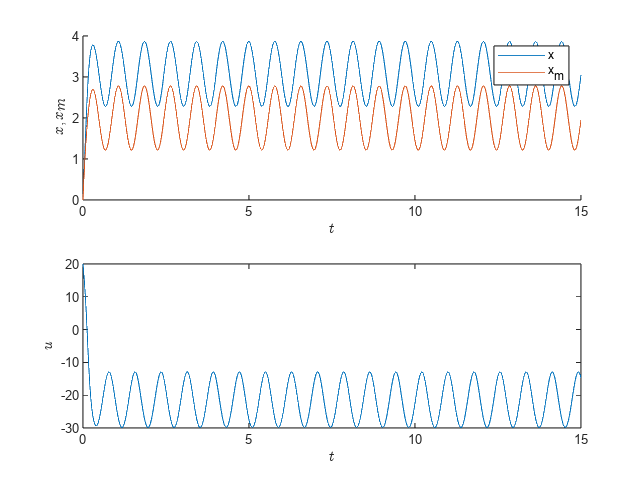

x_0 = 0;
theta_hat_0 = 0;
gamma = 1;

static = sim("Lab2_static.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(static.simout.time, static.simout.signals.values(:,2)); % x
plot(static.simout.time, static.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(static.simout.time, static.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

### 
$$\gamma =5$$


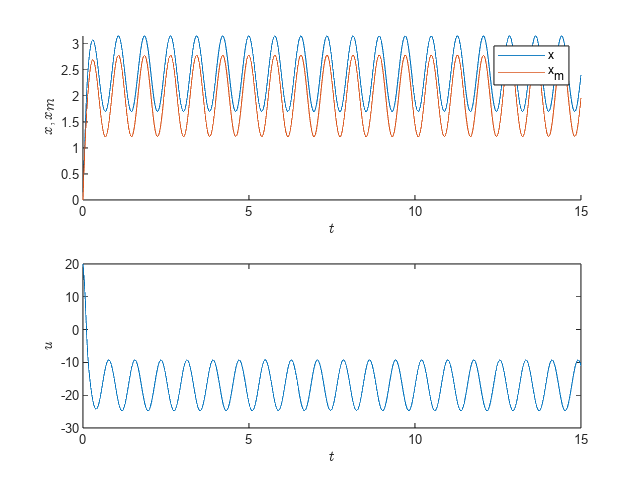

gamma = 5;
static1 = sim("Lab2_static.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(static1.simout.time, static1.simout.signals.values(:,2)); % x
plot(static1.simout.time, static1.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(static1.simout.time, static1.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

### 
$$\gamma =10$$


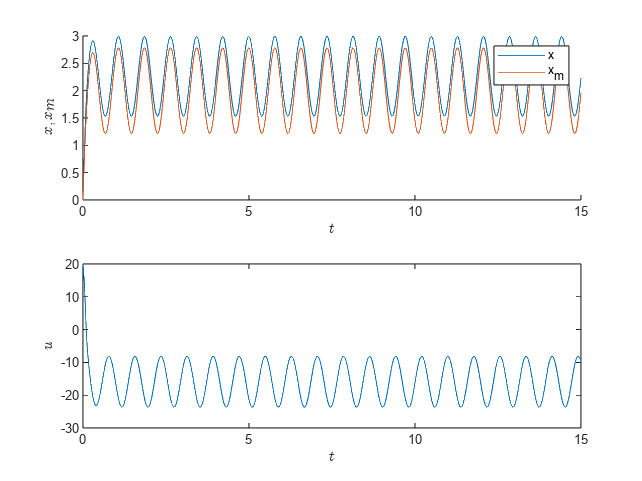

gamma = 10;
static2 = sim("Lab2_static.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(static2.simout.time, static2.simout.signals.values(:,2)); % x
plot(static2.simout.time, static2.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(static2.simout.time, static2.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

Как видно из графиков увеличение $\gamma$ влечет уменьшение расхождения $x\;и\;x_m$.

Но у этого подхода есть недостатки:

- Даже при отсутствии возмущения установившаяся ошибка $\varepsilon \left(t\right)$ может быть отлична от нуля

- Управление пропорционально величине $x^2$ . Следовательно, при росте x амплитуда управления возрастает квадратично, в связи с чем практическая применимость такого закона имеет существенные ограничения. 

## Робастная модификация алгоритма

Рассмотрим третий регулятор. К настраиваемому регулятору добавим алгоритм адаптации, который ограничивает параметрический дрейф с помощью обратой саязи.


$$\dot{\hat{\theta} } =-\sigma \hat{\theta} -\gamma x\varepsilon$$


где $\sigma$ - постоянная положительная величина. Посмотрим, как его варьирование скажется на систему

### 
$$\sigma =1$$


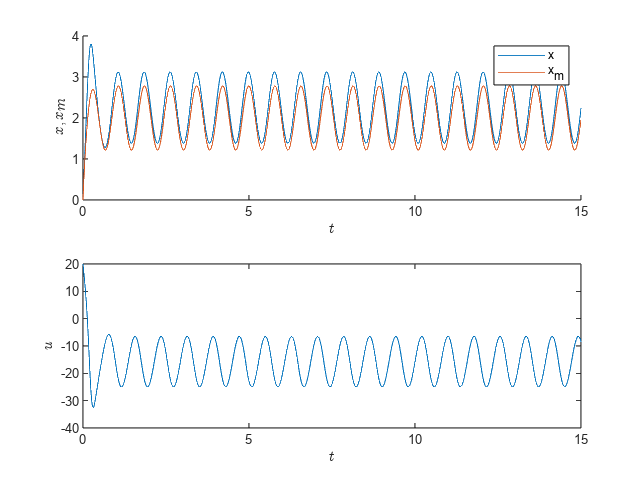

sigma = 1;
robust = sim("Lab2_robust.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(robust.simout.time, robust.simout.signals.values(:,2)); % x
plot(robust.simout.time, robust.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(robust.simout.time, robust.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

### 
$$\sigma =0\ldotp 5$$


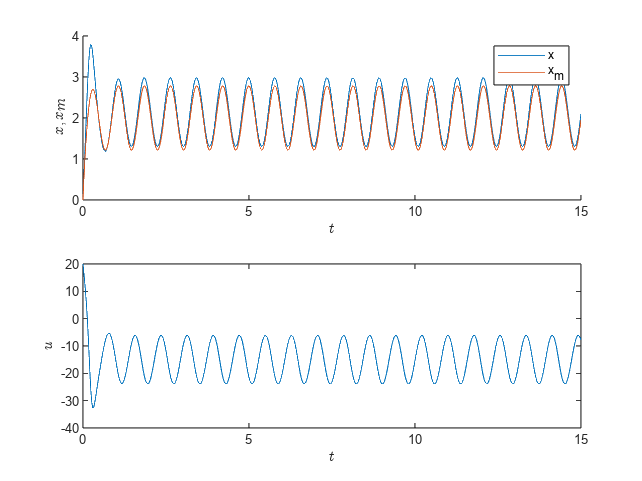

sigma = 0.5;
robust1 = sim("Lab2_robust.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(robust1.simout.time, robust1.simout.signals.values(:,2)); % x
plot(robust1.simout.time, robust1.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(robust1.simout.time, robust1.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

### 
$$\sigma =0\ldotp 1$$


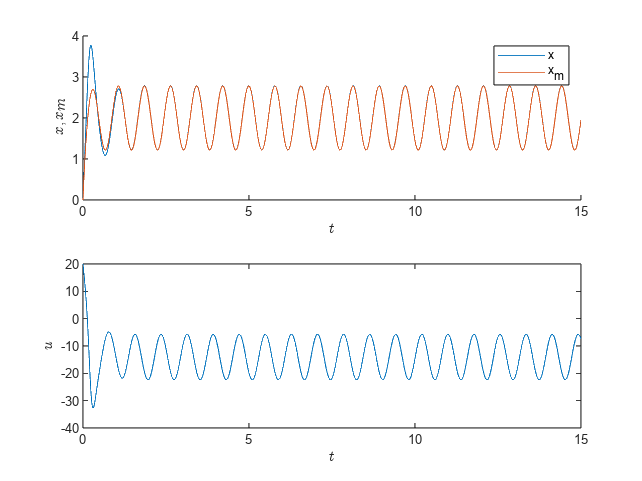

%gamma = 0.01;
sigma = 0.01;

robust2 = sim("Lab2_robust.slx");

% Графики
figure
subplot(2,1,1)
hold on
plot(robust2.simout.time, robust2.simout.signals.values(:,2)); % x
plot(robust2.simout.time, robust2.simout.signals.values(:,3)); % dx
ylabel('$$x, x_m$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')
legend('x','x_m')
hold off
subplot(2,1,2)
plot(robust2.simout.time, robust2.simout.signals.values(:,1)); % u
ylabel('$$u$$','Interpreter','latex')
xlabel('$$t$$','Interpreter','latex')

Как можно увидеть из графиков, уменьшение параметра $\sigma$ ведет к уменьшению ошибки $\varepsilon$.

## Вывод

В работе были рассмотрены 3 регулятора в условиях наличия постоянного возмущения. Показано, что система с простым алгоритмом адаптации не способна оценить параметр в при определенных условиях. Для решения этой проблемы пригодились две модификации:

- С статической обратной связью, из-за большого прирощения управляющего сигнала малопременимого

- Робастная модификация алгоритма адаптации